# Neurotechnology, Brains and Machines: Week 1

Sam Michalka

Much of this should be attributed to *Statistics in MATLAB: A Primer* by MoonJung Cho and Wendy L. Martinez.

Chapters 1-3 (mostly 3) should be an excellent reference for this notebook.

# Intro to Live Editor 

This document introduces you to using Live Editor, walks you through some examples, and contains exercises to complete. I strongly suggest using MATLAB 2016b or later. Like Mathematica and jupyter/python, MATLAB offers a notebook format (.mlx), which is what is open here. The notebook function (Live Editor) allows you to write text in a fancier format than your already beautiflly commented code. 


$$Keeping\; things\; \frac{voltage}{resistance} requires\; \Delta$$


Blue lines separate sections. Text has a white background (or blue if your cursor is in that section). Code has a gray background. You can execute this code by using the "Run Section" button on the top right in the "Live Editor" tab. Or you can press Ctrl+Enter (in Windows).

answertotheultimatequestion = 42

answertotheultimatequestion = 42

This is text that could have been describing the imaginary number below.

u = 1i; %Semicolons suppress output (which is important with large matrices)

You can use Alt+Enter to toggle between text and code.

thisiscode = 4*u %And you can comment without suppressing (or write your comments in the text area... but write them)

thisiscode =    0.0000 + 4.0000i


You can even insert images... like this one that shows you how to toggle between outputs below your code or outputs to the right side of your code.

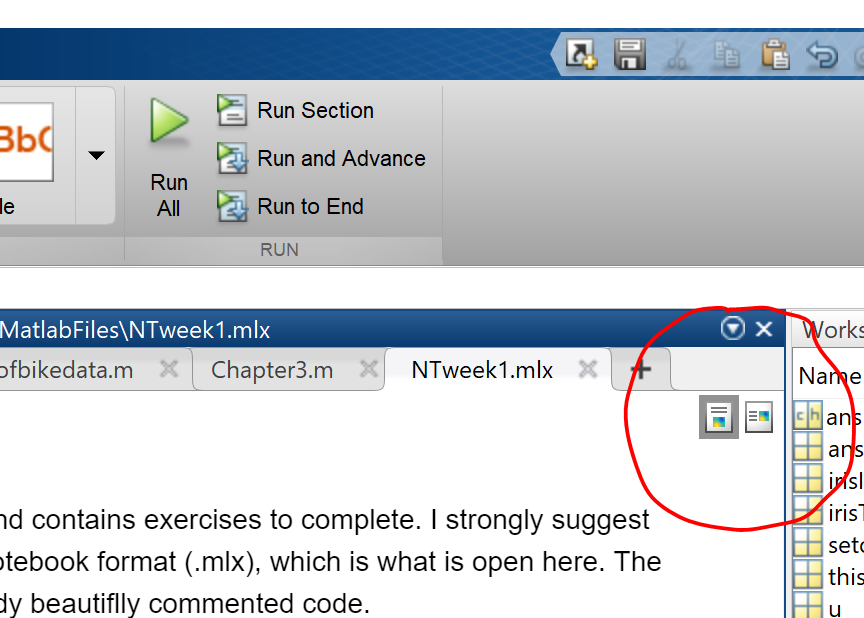

Finally, you can make a Section Break by hitting Ctrl+Alt+Enter.

# New section! Welcome!

This is a nice piece of functionality. 

# Loading and configuring data

First, add the folder that contains your data to your path. Alternatively, you can specify where the files are each time you load them. Or you can make sure your files are in the same directory as your code.

%addpath('StatisticsPrimerDataFiles/')

Let's start by loading some data that is commonly used for analysis examples.  

The data set consists of observations of three species of iris: Iris setosa, Iris virginica, and Iris versicolor. There are 50 observations for each species with 4 measurements—sepal length and width, petal length and width—in centimeters (in that order as columns). They were originally collected by Anderson in 1935 [Anderson, 1935] and were subsequently analyzed by Fisher in 1936 [Fisher, 1936].  (image source: https://rstudio-pubs-static.s3.amazonaws.com/202738_7cad2477d76b4acc82b44244f94ccfa8.html#/1)

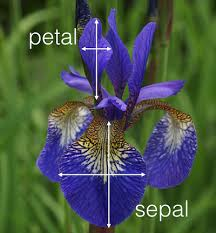

clear answertotheultimatequestion u thisiscode; % You can clear specific variables by calling their names or just use to "clear" to clear them all
load iris.mat

Check your workspace to make sure that there are 3 arrays of size 50 x 4.

whos

  Name             Size             Bytes  Class     Attributes

  allwidths        1x150             1200  double              
  binwidth         1x1                  8  double              
  facealpha        1x1                  8  double              
  setosa          50x4               1600  double              
  versicolor      50x4               1600  double              
  virginica       50x4               1600  double              



## **Tables**

Tables allow you to store data organized with observations as rows and variables as columns. The table format enforces that all the data for a variable are the same data type, such as strings, doubles, ints, etc. (Tables are similar to dataframes in pandas for python users.)

Details here: [https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html](https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html)

For this simple data set, there may not be a distinct advantage to storing our data in a table.  For the sake of getting our heads around tables, we will look at these analysis using both tables and our 3 array variables (setosa, versicolor, and virginica).

% Make a table called irises from an array of our stacked arrays of our 3 species.
iris = array2table([setosa; versicolor; virginica],'VariableNames',{'sepallength','sepalwidth','petallength','petalwidth'});
% Stack the observatations in a known order.

% Generate a new variable in our table called "species" and assign  of the species names that correspond to the known order of our species. We know there are 50 observations for each species.
iris.species = categorical([repmat({'setosa'},50,1); repmat({'versicolor'},50,1);repmat({'virginica'},50,1)]);

# Use histograms and boxplots to get a quick sense of your data

Create a histogram of the Sepal Length 

h = histogram(iris.sepallength) % Unsuppressed so you can see some of the properties

h =   Histogram with properties:

             Data: [150×1 double]
           Values: [4 18 30 31 32 22 7 6]
          NumBins: 8
         BinEdges: [4 4.5000 5 5.5000 6 6.5000 7 7.5000 8]
         BinWidth: 0.5000
        BinLimits: [4 8]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


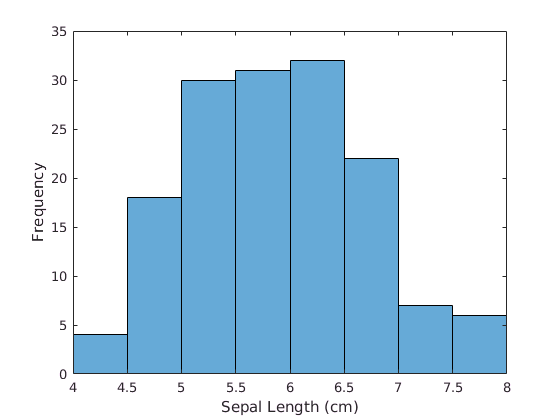

xlabel('Sepal Length (cm)'); ylabel('Frequency');

h = histogram(iris.species) % Unsuppressed so you can see some of the properties

h =   Histogram with properties:

              Data: [150×1 categorical]
            Values: [50 50 50]
    NumDisplayBins: 3
        Categories: {'setosa'  'versicolor'  'virginica'}
      DisplayOrder: 'data'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: 'auto'
         EdgeColor: [0 0 0]

  Show all properties


speciesnames = h.Categories

speciesnames = 1×3 cell array
    'setosa'    'versicolor'    'virginica'


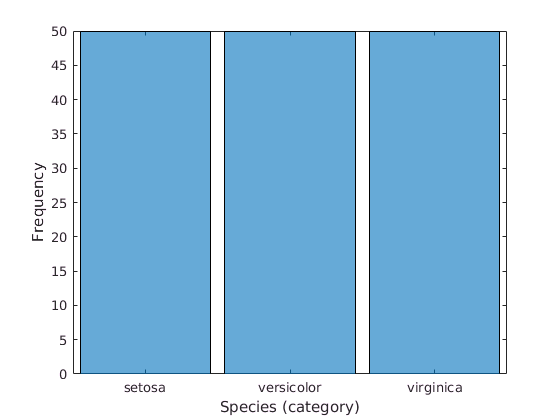

xlabel('Species (category)'); ylabel('Frequency');

Plot a histogram of sepal length for each species on the same figure

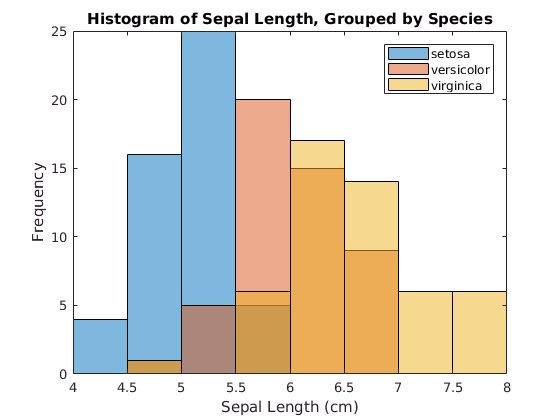

figure
binwidth = 0.5; %Since multiple histograms, we want to align the bin widths
facealpha = 0.5; %transparency of fill colors: 0 to 1
h1 = histogram(iris.sepallength(iris.species=='setosa'),'BinWidth',binwidth,'FaceAlpha',facealpha);
hold on; %make them on the same plot
h2 = histogram(iris.sepallength(iris.species=='versicolor'),'BinWidth',binwidth,'FaceAlpha',facealpha);
h3 = histogram(iris.sepallength(iris.species=='virginica'),'BinWidth',binwidth,'FaceAlpha',facealpha);
ylabel('Frequency'); xlabel('Sepal Length (cm)'); title('Histogram of Sepal Length, Grouped by Species');
legend({'setosa','versicolor','virginica'}); hold off; %Make sure to use hold off, or you'll end up with weird things in your other plots.

## My installation currently lacks the statistics and machine learning toolbox, so I can't make box plots at the moment. It should be fixed soon.

... Nevermind, fixed.

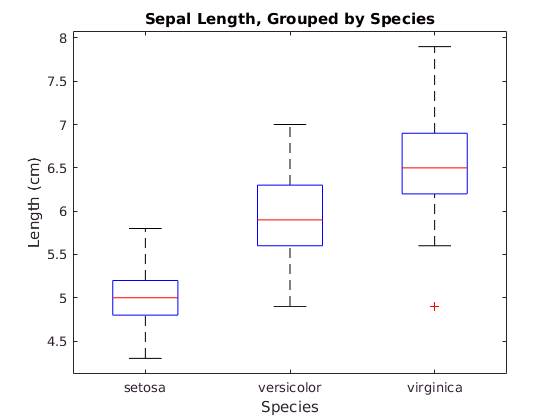

boxplot(iris.sepallength,iris.species); title('Sepal Length, Grouped by Species'); xlabel('Species'); ylabel('Length (cm)');

# Summary statistics

Tables allow you to instantly pull summary statistics of interest.  Keep in mind that these statistics are for all of the iris species combined.

summary(iris)


Variables:

    sepallength: 150×1 double

        Values:

            Min       4.3          
            Median    5.8          
            Max       7.9          

    sepalwidth: 150×1 double

        Values:

            Min         2         
            Median      3         
            Max       4.4         

    petallength: 150×1 double

        Values:

            Min          1         
            Median    4.35         
            Max        6.9         

    petalwidth: 150×1 double

        Values:

            Min       0.1         
            Median    1.3         
            Max       2.5         

    species: 150×1 categorical

        Values:

            setosa        50       
            versicolor    50       
            virginica     50       



**Exercise: Using the 3 arrays that we originally loaded (instead of the table), verify that the ****pedal width**** for all species combined matches the min, max, and median displayed by summary().**

% Build an array to store the petal widths
allwidths = zeros(1,150);
allwidths(1:50)=setosa(:,4)

allwidths =     0.2000    0.2000    0.2000    0.2000    0.2000    0.4000    0.3000    0.2000    0.2000    0.1000    0.2000    0.2000    0.1000    0.1000    0.2000    0.4000    0.4000    0.3000    0.3000    0.3000    0.2000    0.4000    0.2000    0.5000    0.2000    0.2000    0.4000    0.2000    0.2000    0.2000    0.2000    0.4000    0.1000    0.2000    0.2000    0.2000    0.2000    0.1000    0.2000    0.2000    0.3000    0.3000    0.2000    0.6000    0.4000    0.3000    0.2000    0.2000    0.2000    0.2000


allwidths(51:100)=versicolor(:,4)

allwidths =     0.2000    0.2000    0.2000    0.2000    0.2000    0.4000    0.3000    0.2000    0.2000    0.1000    0.2000    0.2000    0.1000    0.1000    0.2000    0.4000    0.4000    0.3000    0.3000    0.3000    0.2000    0.4000    0.2000    0.5000    0.2000    0.2000    0.4000    0.2000    0.2000    0.2000    0.2000    0.4000    0.1000    0.2000    0.2000    0.2000    0.2000    0.1000    0.2000    0.2000    0.3000    0.3000    0.2000    0.6000    0.4000    0.3000    0.2000    0.2000    0.2000    0.2000


allwidths(101:150)=virginica(:,4)

allwidths =     0.2000    0.2000    0.2000    0.2000    0.2000    0.4000    0.3000    0.2000    0.2000    0.1000    0.2000    0.2000    0.1000    0.1000    0.2000    0.4000    0.4000    0.3000    0.3000    0.3000    0.2000    0.4000    0.2000    0.5000    0.2000    0.2000    0.4000    0.2000    0.2000    0.2000    0.2000    0.4000    0.1000    0.2000    0.2000    0.2000    0.2000    0.1000    0.2000    0.2000    0.3000    0.3000    0.2000    0.6000    0.4000    0.3000    0.2000    0.2000    0.2000    0.2000



% Now compute the min, median, and max of the data set we built
min(allwidths)

ans = 0.1000

median(allwidths)

ans = 1.3000

max(allwidths)

ans = 2.5000

**Exercise: Create a histogram and a boxplot of the pedal width for all species combined. For the histogram, set the number of bins to 15.  **

Label your axes where appropriate. You can use the data in table or array format.  Confirm that your values above for the min, median, and max correspond to the appropriate lines on the box plot

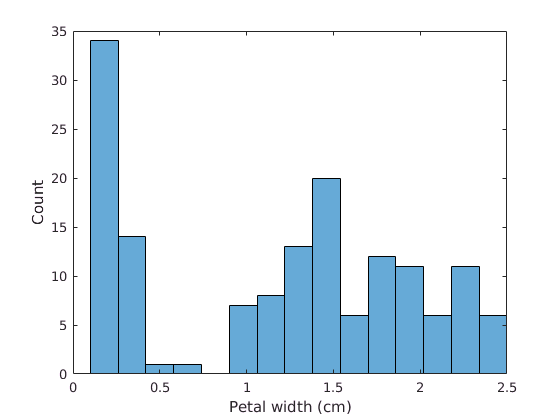

% Answer code goes here

histogram(iris.petalwidth,'NumBins',15)
xlabel('Petal width (cm)')
ylabel('Count')

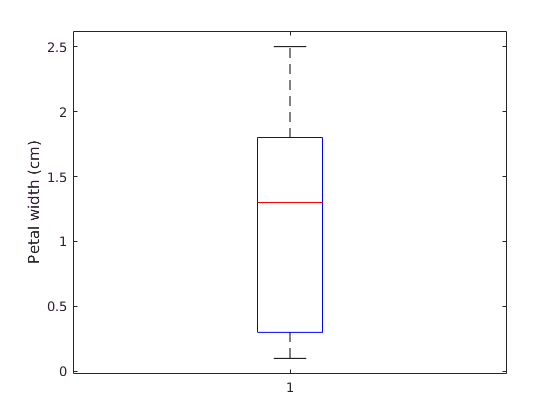


boxplot(iris.petalwidth)
ylabel('Petal width (cm)')

***Super important note about tables: ***Tables are a class in MATLAB that include labels and other metadata. Often functions (like mean) are looking for extracted data or arrays. To get this, make sure you use curly brackets to index your table (if you get an error, this might be your issue). If you index with regular parentheses, the output will be a table. This page has really good details: [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#zmw57dd0e25892](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#zmw57dd0e25892)

iris(1:3,2) %table

ans = 3×1 table
    sepalwidth
    __________

    3.5       
      3       
    3.2       


class(iris(1:3,2))

ans = 'table'

iris{1:3,2} %extracted data

ans =     3.5000
    3.0000
    3.2000


class(iris{1:3,2})

ans = 'double'

iris{1:3,'sepalwidth'} % You can also select columns with their name

ans =     3.5000
    3.0000
    3.2000


We can index the table to choose a subset of the data, such as just the "setosa" species.

rows = (iris.species == 'setosa'); %We can do this because species is a categorical varaible/class. Otherwise, we would need to use strcmp()
mean(iris.sepalwidth(rows)) 

ans = 3.4280

% Or an alternative way to index, whatever floats your boat.
mean(iris{rows,'sepalwidth'})

ans = 3.4280

Or you can summarize for each of the species using varfun and GroupingVariables

varfun(@mean,iris,'InputVariables','sepalwidth','GroupingVariables','species')

ans = 3×3 table
     species      GroupCount    mean_sepalwidth
    __________    __________    _______________

    setosa        50            3.428          
    versicolor    50             2.77          
    virginica     50            2.974          


**Exercise: Verify the me****ans for each species using the array variables **

% Answer code goes here

mean(setosa(:,2))

ans = 3.4280

mean(versicolor(:,2))

ans = 2.7700

mean(virginica(:,2))

ans = 2.9740

**Exercise: Using the table data, create a histogram of the ****sepal length**** of the ****virginica**** species.  **

**Add a solid green ('g-') vertical line at the mean. **

**Add a dashed magenta ('m--') vertical line at the median. **

**Add a dotted blue ('b:') vertical line at the trimmed mean, excluding 30% of values (15% off each end).**

Don't forget to use "hold on" and "hold off". This code will create a green dashed vertical line at "val":

plot([val val],[0 20],'g--','LineWidth',2)

If you use h=histogram(put stuff in here), then you can use to automatically scale these lines:

plot([val val],[0 (5+max(h.Values))],'g--','LineWidth',2)

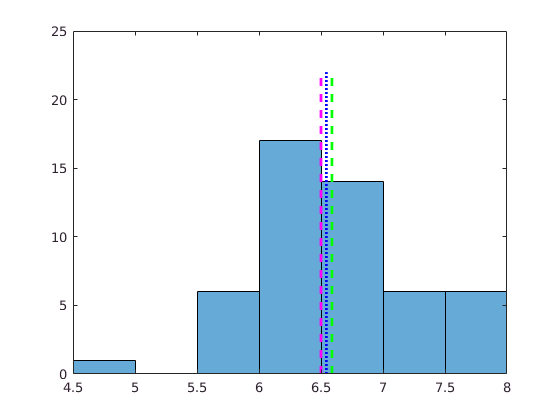

data=iris.sepallength(iris.species=='virginica');
h=histogram(data);
hold on

val=mean(data);
plot([val val],[0 (5+max(h.Values))],'g--','LineWidth',2)

val=median(data);
plot([val val],[0 (5+max(h.Values))],'m--','LineWidth',2)

% With the statistics toolbox (AARGH!!!) there is a nice "trimmean" function.
% I'm just going to do this the hard way.
sorted = sort(data);
newData=sorted(floor(0.15*length(sorted)):ceil(0.85*length(sorted)));
val=mean(newData);
plot([val val],[0 (5+max(h.Values))],'b:','LineWidth',2)

hold off

**Exercise: Repeat the same plot above for 'mydata', given below.**

**Briefly discuss (in words) on the effects of the outliers on the mean, median, and trimmed mean.**

You will need to change the values in plot from 20 to 250 to get a good line.

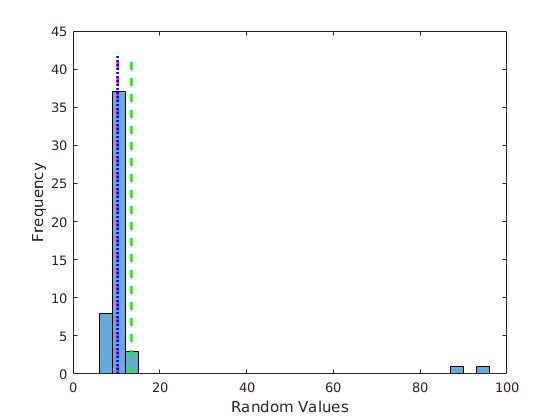

rval = rng('default');%Don't worry about this, just configuring things about random number generator
data = random('Normal',10,1,1,50);
%Uncomment the line below to look at the effect of outliers
data(end-1:end) = [94 87]; %Change the last values to outliers.


% Answer code goes here

h=histogram(data, 30);
hold on

val=mean(data);
plot([val val],[0 (5+max(h.Values))],'g--','LineWidth',2)

val=median(data);
plot([val val],[0 (5+max(h.Values))],'m--','LineWidth',2)

% With the statistics toolbox (AARGH!!!) there is a nice "trimmean" function.
% I'm just going to do this the hard way.
sorted = sort(data);
newData=sorted(floor(0.15*length(sorted)):ceil(0.85*length(sorted)));
val=mean(newData);
plot([val val],[0 (5+max(h.Values))],'b:','LineWidth',2)

hold off
%plot([PUT VALUES HERE],[0 (5+max(h.Values))],'g-','LineWidth',2);
%plot([PUT VALUES HERE],[0 (5+max(h.Values))],'m--','LineWidth',2);
%plot([PUT VALUES HERE],[0 (5+max(h.Values))],'b:','LineWidth',2); hold off
xlabel('Random Values'); ylabel('Frequency');

*As expected, including the outliers substantially affects the mean of the dataset, but has little effect on the median or trimmed mean. There may be explicit outlier detection and rejection mechanisms that do better, but either of those measures do pretty well. The trimmed mean requires more tuning, but could have more reasonable behavior when the data has a bimodal distribution.*

# Measures of dispersion

Variance, standard deviation, mean absolute deviation, range, interquartile range

data = random('Normal',10,1,1,50);
%Uncomment the line below to look at the effect of outliers
%data(end-1:end) = [94 87]; %Change the last values to outliers.

var(data) %variance (specifically sample variance, which uses n-1)

ans = 0.8448

std(data) %sample standard deviation 

ans = 0.9191

sqrt(var(data)) % standard deviation is the square root of the variance

ans = 0.9191

quantile(data,[.25 .50 .75]) %the middle value should be the median

ans =     9.5070   10.1095   10.5939


iqr(data) %interquartile range, should related to the quantile outputs (value for .75 - value for .25)

ans = 1.0869


mad(data) %mean absolute deviation

ans = 0.7295

**Exercise: Briefly discuss the differences between the standard deviation, mean absolute deviation, and interquartile range.  Note the effect of outliers on these measures (which are robust to outliers?).**

The quantiles and iqr data is robust to outliers, which is unsurprising given that they are generalizations of the median, which we established to be robust above.

The mad is less affected by the outlier than the variance or standard deviation, which reflects the fact that differences are magnified by squaring them in the calculation of variance, which means the effect is dominated by the farthest-away values.

**Exercise: Write code using the mathematical formula to calculate the sample standard deviation of mydata and confirm this is matches the value from std()**

% Answer code goes here
sqrt(1/(length(data)-1)*sum((data-mean(data)).^2))

ans = 0.9191

**Exercise: Make a histogram of mydata (no outliers) and include vertical lines at the mean (green), +/- 1 standard deviation from the mean (cyan, 'c'), +/- 2 standard deviations from the mean (blue)**

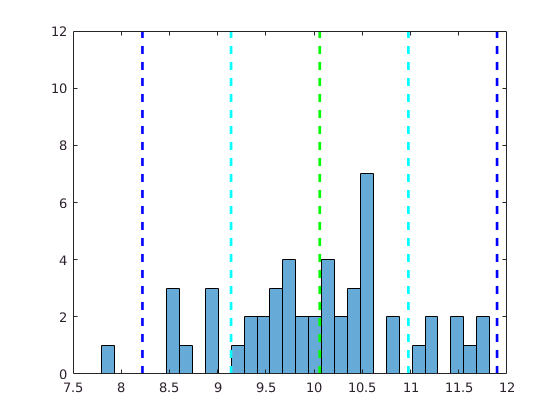

% Answer code goes here
h=histogram(data, 30);
hold on

val=mean(data);
plot([val val],[0 (5+max(h.Values))],'g--','LineWidth',2)

val=mean(data)+std(data);
plot([val val],[0 (5+max(h.Values))],'c--','LineWidth',2)
val=mean(data)-std(data);
plot([val val],[0 (5+max(h.Values))],'c--','LineWidth',2)

val=mean(data)+2*std(data);
plot([val val],[0 (5+max(h.Values))],'b--','LineWidth',2)
val=mean(data)-2*std(data);
plot([val val],[0 (5+max(h.Values))],'b--','LineWidth',2)

hold off

# Correlation and Covariance

Section 3.2.3 in Statistics in Matlab: A Primer discusses correlation and covariance and my be a useful reference.  In general, correlation and covariance are used to describe relationships between variables.

Let's return to our iris data, stored in the table named iris.

Calculate the covariance matrix for the petal lengh and petal width of all species of irises.

cv = cov(iris.petallength,iris.petalwidth)

cv =     3.1163    1.2956
    1.2956    0.5810


The value of cv(1,1) is the variance of the petal lengths. And the value of cv(2,2) is the variance of the petal widths.

var(iris.petallength)

ans = 3.1163

var(iris.petalwidth) == cv(2,2)  %This is a way to test if a statement is true (make sure to use ==, no just =). 1 is true, 0 is false

ans = logical
   1


The covarance between petal length and width is found off the diagonal in cv(1,2) and cv(2,1).  Note that the covariance matrix is symmetric.

We can plot these two variables in relation to each other.

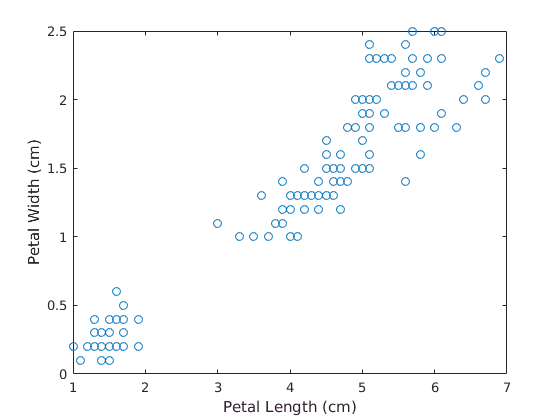

plot(iris.petallength,iris.petalwidth,'o'); xlabel('Petal Length (cm)'); ylabel('Petal Width (cm)');

 The plotmatrix function is a nice way to visualize both the histograms of single variables and the relationships between the varaibles (though the labeling requires some extra work, at least is r2016b). 

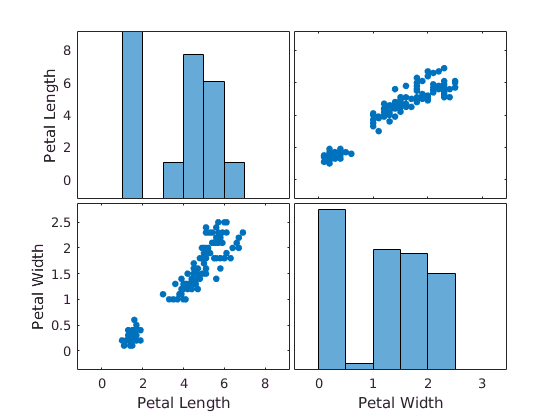

figure;
[~,AX] = plotmatrix(iris{:,3:4});  
AX(1,1).YLabel.String = 'Petal Length';
AX(2,1).YLabel.String = 'Petal Width';
AX(2,1).XLabel.String = 'Petal Length';
AX(2,2).XLabel.String = 'Petal Width';

You can also generate a covariance matrix using a single array, where each row is an observation and each column is a variable (sounds a lot like the data we extract from a table).

cvall = cov(iris{:,1:4})

cvall =     0.6857   -0.0424    1.2743    0.5163
   -0.0424    0.1900   -0.3297   -0.1216
    1.2743   -0.3297    3.1163    1.2956
    0.5163   -0.1216    1.2956    0.5810


colnames = iris.Properties.VariableNames(1:4) %also extract the corresponding variable/column names

colnames = 1×4 cell array
    'sepallength'    'sepalwidth'    'petallength'    'petalwidth'


**Exercise: Find the covariance between the sepal width and petal width, both by indexing in cvall and by calling the cov() function.**

% Answer code goes here
cvall(2,4)

ans = -0.1216

cov(iris.sepalwidth,iris.petalwidth)

ans =     0.1900   -0.1216
   -0.1216    0.5810


The correlation coefficient can be calculated in a similar way. Note that the correlation coefficient is bound between -1 and +1.

crall = corrcoef(iris{:,1:4})

crall =     1.0000   -0.1176    0.8718    0.8179
   -0.1176    1.0000   -0.4284   -0.3661
    0.8718   -0.4284    1.0000    0.9629
    0.8179   -0.3661    0.9629    1.0000


It is often valuable to visualize the covariance and/or correlation matrices.  Note the values in the colorbar legend

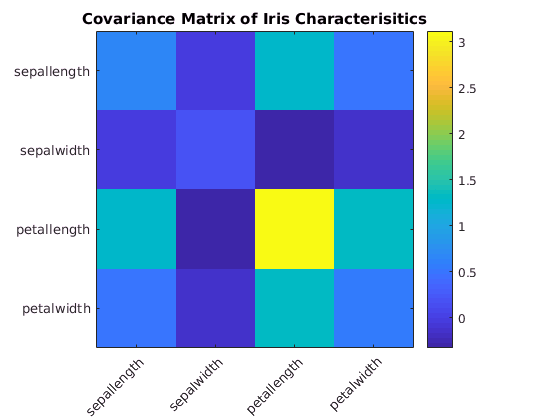

imagesc(cvall); colorbar; axis square; title('Covariance Matrix of Iris Characterisitics')
set(gca,'XTick',1:4, 'XTickLabel',colnames,'XTickLabelRotation',45,...
'YTick',1:4, 'YTickLabel',colnames)

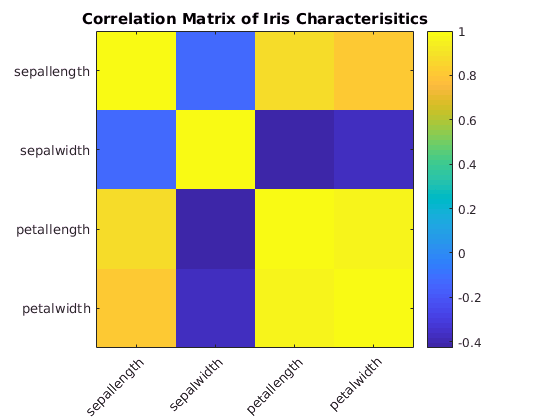

figure
imagesc(crall); colorbar; axis square; title('Correlation Matrix of Iris Characterisitics')
set(gca,'XTick',1:4, 'XTickLabel',colnames,'XTickLabelRotation',45,...
'YTick',1:4, 'YTickLabel',colnames)

**Exercise: Briefly discuss the relationship between covariance and correlation. Give examples of when you might use one measurement over the other.**

*Answer text goes here*

*Correlation is effectivly a normalized representation of the covariance, and as a result, has dimensionless values between -1 and 1. Covariance retains information about the absolute scale of the variations in the original dataset, so the covariance of two datasets is affected by each of their variances. This means that for the same data expressed in two different linearly related unit systems, the numerical value of the covariance will be different, while the numerical values of the correlation will be the same. *

*This effect means that in situations where multiple different data pairs need to be compared with meaningfully different values, correlation will give a more meaningful comparison. For example, comparing the heights and weights of various different animals would benefit from using correlation.*

*In situations where one dataset is being compared to several others, or situations where a data set could have constant value, covariance could make sense. For example, if comparing mouse height to quantities of various foods eaten, a food that all of the subjects ate very similar amounts of should not be considered as having a massive impact on the weight of the mouse, so covariance would allow for eliminating that confounder.*